clear
clc

% cd frames\sick1\

% ///////////////////// INPUT \\\\\\\\\\\\\\\\\\\\\\\

prompt = 'Type in the name of the video (without the video extension): ';
folderName = input(prompt,'s');

prompt = ['Choose the segmentation algorithm:\n    ' ...
    '1) Own implementation of segmentation based on histogram binarization\n    ' ...
    '2) Segementation based on adaptive binarization\n    ' ...
    '3) Watershed segmentation\n\n'];
implementation = input(prompt);

folderPath = '';
filePath = ''; 
switch implementation
    case 1
        folderPath = ['binResults_' folderName]
        filePath = [folderPath '\binSegmentation_']
    case 2
        folderPath = ['adaptiveResults_' folderName]
        filePath = [folderPath '\adaptiveSegmentation_']
    case 3
        folderPath = ['watershedResults_' folderName]
        filePath = [folderPath '\watershedSegmentation_']
    case 4
        folderPath = ['lightResults_' folderName]
        filePath = [folderPath '\lightSegmentation_']
    otherwise
        errordlg('Choose a valid segmentation algorithm','Input Error')
        return
end

folderPath = 'binResults_sick1'

filePath = 'binResults_sick1\binSegmentation_'


prompt = ['Choose the segmentation feature: \n    ' ...
    '1) Redness\n    ' ...
    '2) Gray level\n    ' ...
    '3) Saturation\n    ' ...
    '4) Lightness (similar to gray level, but obtaining the L value from the HSL color scheme)\n\n'];
feature = input(prompt);

if exist(folderPath, 'dir')
    rmdir(folderPath,'s');
end
mkdir(folderPath);

prompt = 'Choose the number of the inital frame:';
initalFrame = input(prompt);
prompt = 'Choose the number of the final frame:';
finalFrame = input(prompt);

% Global Variables 
global S frameIx  previousThreshold previousCentroid
S = dir(fullfile(['.\' folderName '\'],'*.jpg'));
S = natsortfiles(S);

frames = {};
discardedFrames = {};

apertures = [];
aperture = -1;
areas = [];

previousThreshold = -1;
previousAperture = -1;
previousCentroid = [0 0];
minimumAperture = 7;
maximumConsecutiveMisses = 2;
consecutiveMisses = 0; % Counter of the number of consecutive misses
apertureThreshold = 0.8; % Scalar from 0 to 1


% initializing progress bar
f = waitbar(0,'Obtaining frames...');
for frameIx = initalFrame:finalFrame
    
    frameName = fullfile(['.\' folderName],S(frameIx).name)
    frame = imread(frameName);
    
    % updating progress bar
    percentage = (frameIx - initalFrame)/(finalFrame - initalFrame);
    waitbar(percentage,f,'Processing frames...'); 
    validFrame = true;

%     imshow(frame);
%     title('Original Frame');
    
    % //////// PREPROCESSING \\\\\\\\\\
    % ------- Image Cropping ----------
    frameCropped = imcrop(frame,[168,54,387,458]);
%     imshow(frameCropped);
%     title('Cropped Frame');
    % ---------------------------------
    
    % //////// BEST FEATURES \\\\\\\\\\
    % ----------- Redness -------------
    frameRChannel = frameCropped(:,:,1);
    % Create an all black channel.
    allBlack = zeros(size(frameCropped, 1), size(frameCropped, 2), 'uint8');
    % Create a color version of the Red Channel
    frameRed = cat(3, frameRChannel, allBlack, allBlack);
    % Print red channel
%     imshow(frameRed);
%     title('Red Channel only');
    % ---------------------------------
    
    % ----------- Grayness ------------
    frameGray = rgb2gray(frameCropped);
%     imshow(frameGray);
%     title('Gray scale');
    % ---------------------------------
    
    % ----------- Saturation ----------
    framehsv = rgb2hsv(frameCropped);
    frameSaturation = framehsv(:,:,2);
    frameSaturation = abs(frameSaturation - 1);
    % ---------------------------------
    
    % ------------ Light --------------
    hslFrame = rgb2hsl(im2double(frameCropped));
    frameLightness = hslFrame(:,:,3);
    % ---------------------------------
    
    % \\\\\\\\\\\\\\\|/////////////////
    
    preProcessedFrame = [];
    % Filterage of frame
    switch  feature
        case 1
            preProcessedFrame = openCloseByReconstruction(frameRChannel);
        case 2
            preProcessedFrame = openCloseByReconstruction(frameGray);
        case 3
            preProcessedFrame = openCloseByReconstruction(frameSaturation);
        case 4
            preProcessedFrame = openCloseByReconstruction(frameLightness);
    end
    
%     imshow(preProcessedFrame);
%     title('Preprocessed Frame')

    % \\\\\\\\\\\\\\\|/////////////////
    
    % ///////// SEGMENTATION \\\\\\\\\\
        
    binFrame = [];
    switch implementation
        case 1
            try
                % Hist binaritzation
                binFrame = binBinarization(preProcessedFrame,10);
            catch
                sprintf('Error during binBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 2
            try
                % Adaptive binarization
                binFrame = imbinarize(preProcessedFrame,"adaptive", ...
                    "ForegroundPolarity","bright","Sensitivity",0.66);
                binFrame = ~binFrame;
            catch
                sprintf('Error during adaptiveBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 3
            try
                % Watershed segmentation
                binFrame = watershedSegmentation(preProcessedFrame, frameCropped, frameRChannel);
            catch
                sprintf('Error during Watershed segmentation in frame %d',frameIx)
                validFrame = false;
            end
    end
    
    
    % Otsu binarization
%     level = graythresh(preProcessedFrame);
%     binFrameOtsu = imbinarize(preProcessedFrame,level);

    % ---------------------------------
    % \\\\\\\\\\\\\\\|/////////////////
    
    % //////// POSTPROCESSING \\\\\\\\\\
    try
        if validFrame
            closeDiffBlobFrame = getSegment(binFrame);
        end
    catch
        sprintf('Error during funciton getSegmet of frame %d', frameIx)
        validFrame = false;
    end
    % \\\\\\\\\\\\\\\|/////////////////
    
    % Getting the area
    if validFrame
        maxDiffArea = bwarea(closeDiffBlobFrame);
    end
    
    if validFrame
        try
            aperture = getStenosisDegree(frameCropped, closeDiffBlobFrame, ['\' filePath]);
        catch
            sprintf('Error while getting the stenosis degree of frame %f', frameIx)
        end
        if previousAperture == -1 && aperture > minimumAperture
            previousAperture = aperture;
        elseif aperture < minimumAperture
            validFrame = false;
        end
    end
    % \\\\\\\\\\\\\\\|/////////////////
        
    % Adaptive result
%     secondFig = figure('visible','off');
%     segmentationOutline(frameCropped, closeAdaptiveBlobFrame);
%     title('Segmentation outline based on adaptive binarization');
%     saveas(secondFig,[pwd '\adaptiveResultsSick1\adaptiveSegmentation_' S(frameIx).name]);
    
    % Watershed result
%     thirdFig = figure('visible','off');
%     segmentationOutline(frameCropped, watershedSegmentation);
%     title('Segmentation outline based on watersheding with local minimum and maxima');
%     saveas(thirdFig,[pwd '\watershedResultsSick1\watershedSegmentation_' S(frameIx).name]);

    % ---------- Saving results -------------- %
    validAperture = false;
    if validFrame
        if aperture < previousAperture + previousAperture*apertureThreshold && ...
            aperture > previousAperture - previousAperture*apertureThreshold
        validAperture = true;
        end 
    end
    
    if (validFrame && validAperture) || (consecutiveMisses >= maximumConsecutiveMisses && aperture > minimumAperture)
        frames{end + 1} = S(frameIx).name;
        apertures = [apertures aperture];
        previousAperture = aperture;
        validFrame = true;
        consecutiveMisses = 0;
    else
        previousThreshold = - 1;
        previousAperture
        aperture
        discardedFrames{end + 1}= S(frameIx).name;
        consecutiveMisses = consecutiveMisses + 1;
    end
    % ---------------------------------------- %
end 

frameName = '.\sick1\1.jpg'

frameName = '.\sick1\2.jpg'

frameName = '.\sick1\3.jpg'

frameName = '.\sick1\4.jpg'

frameName = '.\sick1\5.jpg'

frameName = '.\sick1\6.jpg'

frameName = '.\sick1\7.jpg'

frameName = '.\sick1\8.jpg'

frameName = '.\sick1\9.jpg'

frameName = '.\sick1\10.jpg'

frameName = '.\sick1\11.jpg'

frameName = '.\sick1\12.jpg'

frameName = '.\sick1\13.jpg'

frameName = '.\sick1\14.jpg'

frameName = '.\sick1\15.jpg'

frameName = '.\sick1\16.jpg'

frameName = '.\sick1\17.jpg'

frameName = '.\sick1\18.jpg'

frameName = '.\sick1\19.jpg'

frameName = '.\sick1\20.jpg'

frameName = '.\sick1\21.jpg'

frameName = '.\sick1\22.jpg'

frameName = '.\sick1\23.jpg'

frameName = '.\sick1\24.jpg'

frameName = '.\sick1\25.jpg'

frameName = '.\sick1\26.jpg'

frameName = '.\sick1\27.jpg'

frameName = '.\sick1\28.jpg'

frameName = '.\sick1\29.jpg'

frameName = '.\sick1\30.jpg'

frameName = '.\sick1\31.jpg'

frameName = '.\sick1\32.jpg'

frameName = '.\sick1\33.jpg'

frameName = '.\sick1\34.jpg'

frameName = '.\sick1\35.jpg'

frameName = '.\sick1\36.jpg'

frameName = '.\sick1\37.jpg'

frameName = '.\sick1\38.jpg'

frameName = '.\sick1\39.jpg'

frameName = '.\sick1\40.jpg'

frameName = '.\sick1\41.jpg'

frameName = '.\sick1\42.jpg'

frameName = '.\sick1\43.jpg'

frameName = '.\sick1\44.jpg'

frameName = '.\sick1\45.jpg'

frameName = '.\sick1\46.jpg'

frameName = '.\sick1\47.jpg'

frameName = '.\sick1\48.jpg'

frameName = '.\sick1\49.jpg'

frameName = '.\sick1\50.jpg'

frameName = '.\sick1\51.jpg'

frameName = '.\sick1\52.jpg'

frameName = '.\sick1\53.jpg'

frameName = '.\sick1\54.jpg'

frameName = '.\sick1\55.jpg'

frameName = '.\sick1\56.jpg'

frameName = '.\sick1\57.jpg'

frameName = '.\sick1\58.jpg'

frameName = '.\sick1\59.jpg'

frameName = '.\sick1\60.jpg'

frameName = '.\sick1\61.jpg'

frameName = '.\sick1\62.jpg'

frameName = '.\sick1\63.jpg'

frameName = '.\sick1\64.jpg'

frameName = '.\sick1\65.jpg'

frameName = '.\sick1\66.jpg'

frameName = '.\sick1\67.jpg'

frameName = '.\sick1\68.jpg'

frameName = '.\sick1\69.jpg'

frameName = '.\sick1\70.jpg'

frameName = '.\sick1\71.jpg'

frameName = '.\sick1\72.jpg'

frameName = '.\sick1\73.jpg'

frameName = '.\sick1\74.jpg'

frameName = '.\sick1\75.jpg'

frameName = '.\sick1\76.jpg'

frameName = '.\sick1\77.jpg'

frameName = '.\sick1\78.jpg'

frameName = '.\sick1\79.jpg'

frameName = '.\sick1\80.jpg'

frameName = '.\sick1\81.jpg'

frameName = '.\sick1\82.jpg'

frameName = '.\sick1\83.jpg'

frameName = '.\sick1\84.jpg'

frameName = '.\sick1\85.jpg'

frameName = '.\sick1\86.jpg'

frameName = '.\sick1\87.jpg'

frameName = '.\sick1\88.jpg'

frameName = '.\sick1\89.jpg'

frameName = '.\sick1\90.jpg'

frameName = '.\sick1\91.jpg'

frameName = '.\sick1\92.jpg'

frameName = '.\sick1\93.jpg'

frameName = '.\sick1\94.jpg'

frameName = '.\sick1\95.jpg'

frameName = '.\sick1\96.jpg'

frameName = '.\sick1\97.jpg'

frameName = '.\sick1\98.jpg'

frameName = '.\sick1\99.jpg'

frameName = '.\sick1\100.jpg'

frameName = '.\sick1\101.jpg'

frameName = '.\sick1\102.jpg'

frameName = '.\sick1\103.jpg'

frameName = '.\sick1\104.jpg'

frameName = '.\sick1\105.jpg'

frameName = '.\sick1\106.jpg'

frameName = '.\sick1\107.jpg'

frameName = '.\sick1\108.jpg'

frameName = '.\sick1\109.jpg'

frameName = '.\sick1\110.jpg'

frameName = '.\sick1\111.jpg'

frameName = '.\sick1\112.jpg'

frameName = '.\sick1\113.jpg'

frameName = '.\sick1\114.jpg'

frameName = '.\sick1\115.jpg'

frameName = '.\sick1\116.jpg'

frameName = '.\sick1\117.jpg'

frameName = '.\sick1\118.jpg'

frameName = '.\sick1\119.jpg'

frameName = '.\sick1\120.jpg'

frameName = '.\sick1\121.jpg'

frameName = '.\sick1\122.jpg'

frameName = '.\sick1\123.jpg'

frameName = '.\sick1\124.jpg'

frameName = '.\sick1\125.jpg'

frameName = '.\sick1\126.jpg'

frameName = '.\sick1\127.jpg'

frameName = '.\sick1\128.jpg'

frameName = '.\sick1\129.jpg'

frameName = '.\sick1\130.jpg'

frameName = '.\sick1\131.jpg'

frameName = '.\sick1\132.jpg'

frameName = '.\sick1\133.jpg'

frameName = '.\sick1\134.jpg'

frameName = '.\sick1\135.jpg'

frameName = '.\sick1\136.jpg'

frameName = '.\sick1\137.jpg'

frameName = '.\sick1\138.jpg'

frameName = '.\sick1\139.jpg'

frameName = '.\sick1\140.jpg'

previousAperture = 45.8039

aperture = 91.9837

frameName = '.\sick1\141.jpg'

previousAperture = 45.8039

aperture = 129.7112

frameName = '.\sick1\142.jpg'

frameName = '.\sick1\143.jpg'

frameName = '.\sick1\144.jpg'

frameName = '.\sick1\145.jpg'

frameName = '.\sick1\146.jpg'

frameName = '.\sick1\147.jpg'

frameName = '.\sick1\148.jpg'

frameName = '.\sick1\149.jpg'

frameName = '.\sick1\150.jpg'


% closing progress bar
close(f)

% ///////////// RESULTS \\\\\\\\\\\\\\\

T = table(frames',apertures')

T = 148×2 table
       Var1        Var2 
    __________    ______

    {'1.jpg' }    56.648
    {'2.jpg' }    59.464
    {'3.jpg' }    91.782
    {'4.jpg' }    82.976
    {'5.jpg' }    83.199
    {'6.jpg' }    80.808
    {'7.jpg' }    88.459
    {'8.jpg' }    89.944
    {'9.jpg' }    86.579
    {'10.jpg'}    84.717
    {'11.jpg'}    81.884
    {'12.jpg'}    79.906
    {'13.jpg'}    79.076
    {'14.jpg'}    54.781
    {'15.jpg'}    55.714
    {'16.jpg'}    50.695


% Standard Deviation of the valid apertures
variance = var(apertures)

variance = 2.3944e+03

standardDeviation = std(apertures)

standardDeviation = 48.9331

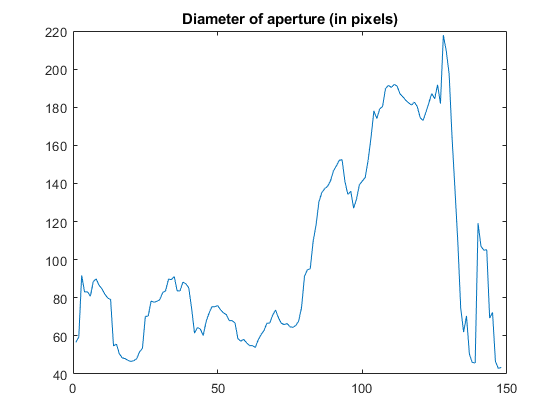


figure
plot(apertures)
title('Diameter of aperture (in pixels)')

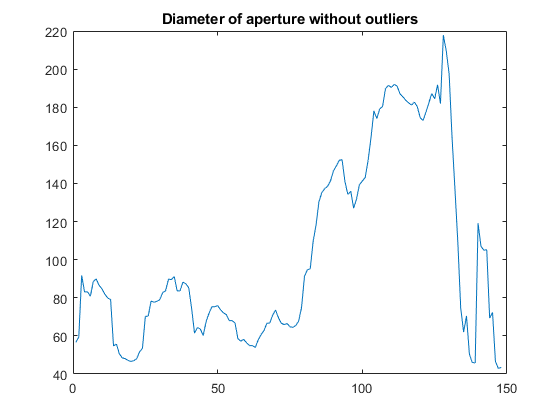


apertures = rmoutliers(apertures, 'quartiles');
plot(apertures)
title('Diameter of aperture without outliers')

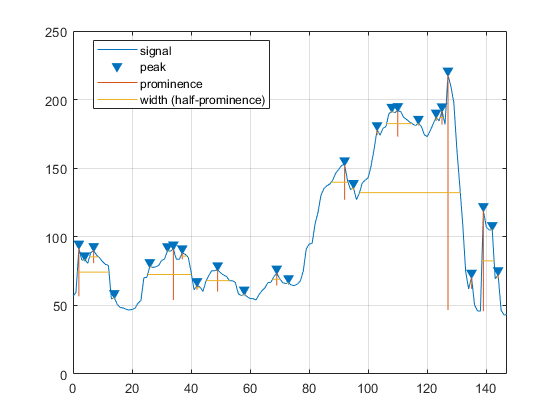


% Finding peaks
peaksIx = [1:size(apertures)];
[peaks, locs, p] = findpeaks(apertures,peaksIx,'Annotate','extents');
figure
findpeaks(apertures,peaksIx,'Annotate','extents')

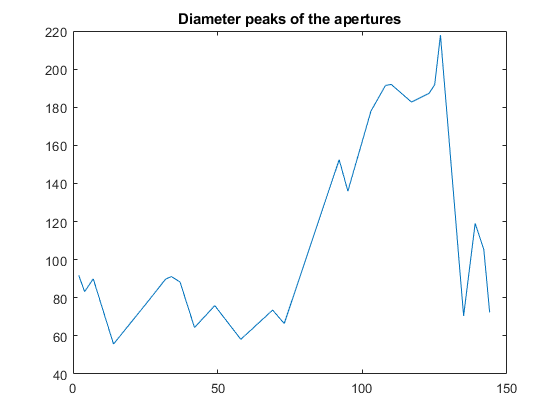


figure
plot(locs,peaks)
title('Diameter peaks of the apertures')

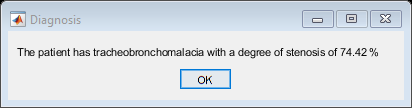


% Getting the biggest difference in the peaks
[minVal, minIx] = min(peaks);
[maxVal, maxIx] = max(peaks);
result = maxVal - minVal;

% Getting the difference on the degree of stenosis
degreeDiff = 100 - (minVal*100 / maxVal);

% Printing the results
formatStruct.Interpreter = 'tex';
formatStruct.WindowStyle = 'modal';
if degreeDiff > 50
    msgbox(sprintf('The patient has tracheobronchomalacia with a degree of stenosis of %.2f %%',degreeDiff),'Diagnosis',formatStruct)
else
    msgbox('The patient does not have tracheobronchomalacia','Diagnosis',formatStruct)
end


% \\\\\\\\\\\\\\\\\//////////////////

% cd ..\..\


function watershedSegmentation = watershedSegmentation(preProcessedFrame, frameCropped, frame)
    % ---------- Watershed ------------
    maximums = imregionalmax(preProcessedFrame);
%     figure
%     imshow(maximums)
%     title('Regional Maxima of Opening-Closing by Reconstruction')
    
    minimums = imregionalmin(preProcessedFrame);
%     figure
%     imshow(minimums)
%     title('Regional Minimums of Opening-Closing by Reconstruction')
    
    minimum = extractClosestBlob(minimums, [size(frameCropped,1) / 2 size(frameCropped,2) / 2]);
%     figure
%     imshow(minimum)
%     title('Regional biggest minimum of Opening-Closing by Reconstruction')
    
    D = bwdist(maximums | minimums);
    DL = watershed(D);
    bgm = DL == 0;
%     figure
%     imshow(bgm)
%     title('Watershed Ridge Lines')
    
    I2 = labeloverlay(frame,minimums | maximums);
%     figure
%     imshow(I2)
%     title('Regional Minimum and Maxima Superimposed on Original Image')
    
    se2 = strel(ones(5,5));
    fgm2 = imclose(minimums | maximums,se2);
    fgm3 = imerode(fgm2,se2);
    fgm4 = bwareaopen(fgm3,20);
    I3 = labeloverlay(frame,fgm4);
%     figure
%     imshow(I3)
%     title('Modified Regional Maxima Superimposed on Original Image')
    
    % Gradient of the image
    gmag = imgradient(frame);
%     figure
%     imshow(gmag,[]);
%     title('Image gradient')
    
    gmag2 = imimposemin(gmag, fgm4);
    figure
%     imshow(gmag2,[])
%     title('Gradient with markers imposed')
    L = watershed(gmag2);
    labels = imdilate(L==0,ones(3,3)) + 2*(minimums | maximums) + 3*fgm4;
    I4 = labeloverlay(frame,labels);
%     figure
%     imshow(I4)
%     title('Markers and Object Boundaries Superimposed on Original Image')
    % labeling the watershed results
    Lrgb = label2rgb(L,'jet','w','shuffle');
%     figure
%     imshow(Lrgb)
%     title('Colored Watershed Label Matrix')
    % Getting the the value of the labels for the biggest minimum blob in the frame
    labelValue = L(minimum);
    % Getting the label with maximum ocurrence
    value = mode(labelValue);
    % Getting the watershed segmentation of the stenosis level
    watershedSegmentation= L == value;
%     figure
%     imshow(watershedSegmentation);
%     title('Watershed final mask')
    % ---------------------------------
end

function aperture = getStenosisDegree(frameCropped, frameMask, path)
    global S frameIx previousCentroid
    %  --------- Getting the degree of aperture and saving the image -------
        % Max diff result
        edgeDetected = edge(frameMask,"canny");
        frameOutlined = imoverlay(frameCropped,edgeDetected,'yellow');
        
        firstFig = figure('visible','off');
%         firstFig = figure;
        imshow(frameOutlined);
    
        stats = regionprops(frameMask, 'Centroid', 'BoundingBox', ...
            'Orientation', 'MinFeretProperties');
        
        % If there are more than on blob, I get the closest to the centroid of
        % the last frame with a valid centroid
        ixStats = 1; % Index of the stats struct
        if numel(stats) > 1
            centroids = [stats.Centroid];
            centroids = reshape(centroids,2,2).';
            [k, dist] = dsearchn(previousCentroid,centroids);
            [~, ixStats] = min(dist);
            centroid = stats(ixStats).Centroid;
        else
            centroid = stats.Centroid;
        end
        
        bbox = stats(ixStats).BoundingBox;
        orientation = stats(ixStats).Orientation; % Getting the perpendicular orientation
        minorAxisLen = stats(ixStats).MinFeretDiameter;
        
%         xCentroid = stats(ixStats).Centroid(1);
        xCentroid = bbox(1) + bbox(3)/2;
        yCentroid = stats(ixStats).Centroid(2);
        previousCentroid = [xCentroid yCentroid];
        
        % Calculating the aperture using the orientation of the blob
        % and the centroid
        sinOrient = sind(orientation);
        cosOrient = cosd(orientation);
        
        vertUpperDist = 0;
        vertLowerDist = 0;
        if orientation < 135 && orientation > -45 
            vertUpperDist = pdist([xCentroid, yCentroid; xCentroid, bbox(2), ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; xCentroid, (bbox(2) + bbox(4))],'euclidean');
        else
            vertUpperDist = pdist([xCentroid, yCentroid; bbox(1), yCentroid, ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; (bbox(1) + bbox(3)) ,yCentroid],'euclidean');
        end
        % Calculing the endpoints of the line of aperture from the centroid,
        % adding the relative distance to the bounding box plus a half
        xCoords(1) = xCentroid + (vertUpperDist + vertUpperDist/2) * sinOrient;
        yCoords(1) = yCentroid + (vertUpperDist + vertUpperDist/2) * cosOrient;
        xCoords(2) = xCentroid - (vertLowerDist + vertLowerDist/2) * sinOrient;
        yCoords(2) = yCentroid - (vertLowerDist + vertLowerDist/2) * cosOrient;
        
        % Distance between the two endpoints of the line
        nPoints = ceil(sqrt((xCoords(2) - xCoords(1)).^2 + (yCoords(2) - yCoords(1)).^2)) + 1;
        
        % X and Y values of the endpoints
        xvalues = round(linspace(xCoords(1), xCoords(2), nPoints));
        yvalues = round(linspace(yCoords(1), yCoords(2), nPoints));
        
        % Cropping the aperture pixels that surpass the bounding box of the blob
        if orientation < 135 && orientation > -45 
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        else
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        end
        
        % Mask the values of intercection of the line with the edge of the segmentation mask 
        lineMask = false(size(edgeDetected,1),size(edgeDetected,2));
        lineMask(sub2ind(size(lineMask), yvalues, xvalues)) = 1;
        
        % Dilating the line to ensure that it intersects with the edge
        lineMask = imdilate(lineMask,strel('line',5,orientation));
        lineMask = edgeDetected .* lineMask;
        
        % Values of the two farthest points of the line¡
        [row1,col1] = find(lineMask, 1, 'first');
        [row2,col2] = find(lineMask, 1, 'last');
        midpoint = ([row1 col1] + [row2 col2]).'/2;
        aperture = pdist([row1, col1; row2, col2],'euclidean');
        
        % Plot of all the data on top of the original image
        hold on;
        plot([col1,col2],[row1,row2],'c','LineWidth',2)
        plot(xCentroid, yCentroid, 'r+', 'LineWidth', 2, 'MarkerSize', 7)
        rectangle('Position',bbox,"EdgeColor",'b')
        title('Segmentation outline with the degree of stenosis');
        text(midpoint(2) + 20,midpoint(1),string(aperture),'Color',[0 1 1],'FontSize',8)
        saveas(firstFig,[pwd path S(frameIx).name]);
end

function mask = binBinarization(frame,bins)
    global previousThreshold
    [counts,binLocations] = imhist(frame,bins);
    % Getting first local maxima in the hist with a threshold of 500
    % I use this threshold to ignore small local peaks
    [pks,locs] = findpeaks(counts,'MinPeakHeight',6000);
    if not(isempty(pks)) 
        ix = locs(1) - 1; %indexing to the previous bin for the calculus
        % Setting the threshold using the % of divergence between bins
        countDiff = (counts(ix) * 100) / counts(ix + 1);
        binDiff = binLocations(ix + 1) - binLocations(ix);
        binThresh = binLocations(ix) + binDiff * ((100-countDiff)/100);       
    else
        diffs = diff(counts);
        [maxDiff, diffIx] = max(diffs(diffs>=0));
        countDiff = (counts(diffIx) * 100) / counts(diffIx + 1);
        binDiff = binLocations(diffIx + 1) - binLocations(diffIx);
        binThresh = binLocations(diffIx) + binDiff * ((100-countDiff)/100);
    end
    % The previous threshold is taken into account in order to get more
    % accurate results
    if previousThreshold ~= -1
        threshDiff = binThresh - previousThreshold;
        if threshDiff >= 0
            percentageOfDiff = previousThreshold*100 / binThresh;
            binThresh = binThresh - threshDiff*(percentageOfDiff/100);
        else
            percentageOfDiff = binThresh*100 / previousThreshold;
            binThresh = binThresh + abs(threshDiff)*(percentageOfDiff/100);
        end
    end
    previousThreshold = binThresh;
    mask = frame <= binThresh;    
end

function segmentationOutline(frame, segmentation)
    edgeDetected = edge(segmentation,"canny");
    frameOutlined = imoverlay(frame,edgeDetected,'yellow');
    imshow(frameOutlined);
end

function openClosedImage = openCloseByReconstruction(frame)    
    se = strel('disk',20);
    Io = imopen(frame,se);
%     imshow(Io)
%     title('Opening')
%     figure
    
    Ie = imerode(frame,se);
    Iobr = imreconstruct(Ie,frame);
%     imshow(Iobr)
%     title('Opening-by-Reconstruction')
%     figure
    
    Ioc = imclose(Io,se);
%     imshow(Ioc)
%     title('Opening-Closing')
%     figure
    
    Iobrd = imdilate(Iobr,se);
    IocRecon = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
    openClosedImage = imcomplement(IocRecon);
%     imshow(openClosedImage)
%     title('Opening-Closing by Reconstruction')
%     figure
end

function binaryImage = extractClosestBlob(binaryImage, point)
    try
      % Get all the Centroids
      [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
      blobStats = regionprops(labeledImage, 'Centroid');
      allCentroids = [blobStats.Centroid];
      allCentroids = reshape(allCentroids,2,[]).';
        
      % Get the closest Blob to the point
      [k, dist] = dsearchn(point,allCentroids);
      [~, ixStats] = min(dist);
      
      % Extract the blob using ismember().
      biggestBlob = ismember(labeledImage, ixStats);
      % Convert from integer labeled image into binary (logical) image.
      binaryImage = biggestBlob > 0;
      
    catch ME
      errorMessage = sprintf('Error in function extractClosestBlob().\n\nError Message:\n%s', ME.message);
      fprintf(1, '%s\n', errorMessage);
      uiwait(warndlg(errorMessage));
    end
end

function segmentFrame = getSegment(binFrame)
    % -------- Filling holes ----------
    filledFrame = imfill(binFrame,8,'holes');
%     imshow(filledFrame);
%     title('Binarization with filled holes');
%     figure
    % ---------------------------------
    
    % ---------- Closing gaps ---------
    % With disks
    % SE = strel('disk',15,8);
    % closedFrame = imclose(filledFrame,SE);
    % imshow(closedFrame); % Circle closed
    % closedFilledFrame = imfill(closedFrame,8,'holes');
    % imshow(closedFilledFrame);
    
    % With lines
    positiveSlope = strel('line',15,45);
    negativeSlope = strel('line',15,-45);
    horizontalLine = strel('line',15,0);
    verticalLine = strel('line',15,90);
    closedFrame=imclose(filledFrame,positiveSlope);
    closedFrame=imclose(closedFrame,negativeSlope);
    closedFrame=imclose(closedFrame,horizontalLine);
    closedFrame=imclose(closedFrame,verticalLine);
    closedFilledFrame = imfill(closedFrame,8,'holes');
%     imshow(closedFilledFrame);
%     title('Closed frame with gaps filled');
%     figure
    % ---------------------------------
    
    % -- Removing small Conn. Comp. ---
    props = regionprops(closedFilledFrame, 'Area');
    allAreas = [props.Area];
    cleanedFrame = bwareaopen(closedFilledFrame, ceil(max(allAreas)*0.75));
%     imshow(cleanedFrame);
%     title('Removal of unnecessary connected components and filling gaps');
%     figure
    % ---- Extracting largest Blobs ---
    % blobFrame = ExtractNLargestBlobs(cleanedFrame, 1);
    % imshow(blobFrame);
    positiveSlope = strel('line',25,45);
    negativeSlope = strel('line',25,-45);
    horizontal = strel('line',25,0);
    vertical = strel('line',25,90);
    closeBlobFrame=imclose(cleanedFrame,positiveSlope);
    closeBlobFrame=imclose(closeBlobFrame,negativeSlope);
    closeBlobFrame=imclose(closeBlobFrame,horizontal);
    closeBlobFrame=imclose(closeBlobFrame,vertical);
    closeBlobFrame = imfill(closeBlobFrame,8,'holes');
%     imshow(closeBlobFrame);
%     title('Final segmentation mask');
%     figure
    segmentFrame = closeBlobFrame;
    % ---------------------------------
    % ---------------------------------
    
    % ----- Threading the needle ------
    % ---------- Convex hull ----------
    % unionFrame = bwconvhull(blobFrame, 'Union');
    % imshow(unionFrame);
    % ---------------------------------
    % -------- Active Countour --------
    %numberOfIterations = 100;
    %bw = activecontour(frameRChannel, unionFrame, numberOfIterations, 'edge');
    %imshow(bw);
    % ---------------------------------
    % ---------------------------------
end